MAX_MOVES = 200;

Here we will run the experiment for map one

map = rand(200, 200);
map(map==0) = 1;
drone = Drone(map, 100, 100, 7);

Warning!!! Max speed of drone is too great for the sensing capability currently set. The drone may fly faster than its sensing area.


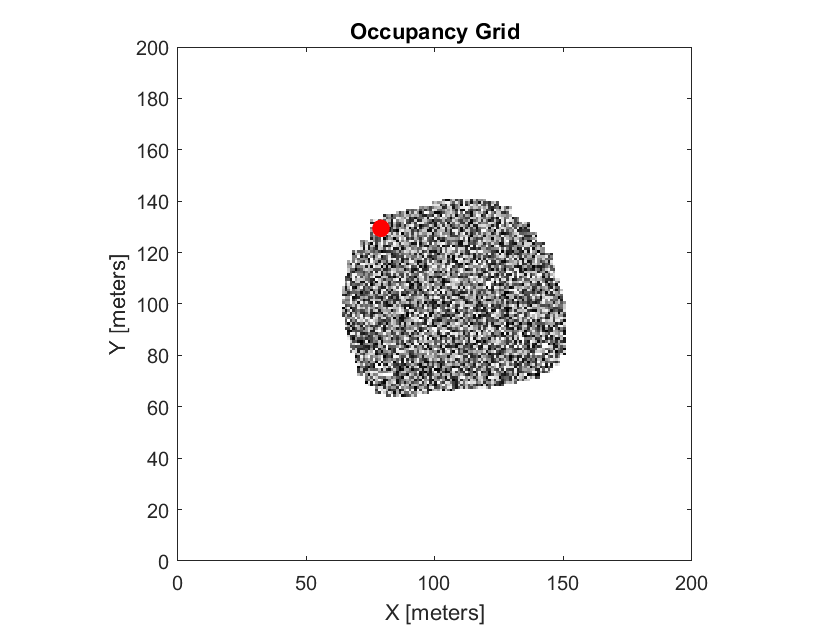

[drone, poses] = Dynamic_Pathfinding_Algorithm(drone, MAX_MOVES);

dynamicPathfindingPercent = getDroneStats(drone, poses)

dynamicPathfindingPercent = 0.1365

map = rand(200, 200);
map(map==0) = 1;
drone = Drone(map, 100, 100, 7);

Warning!!! Max speed of drone is too great for the sensing capability currently set. The drone may fly faster than its sensing area.


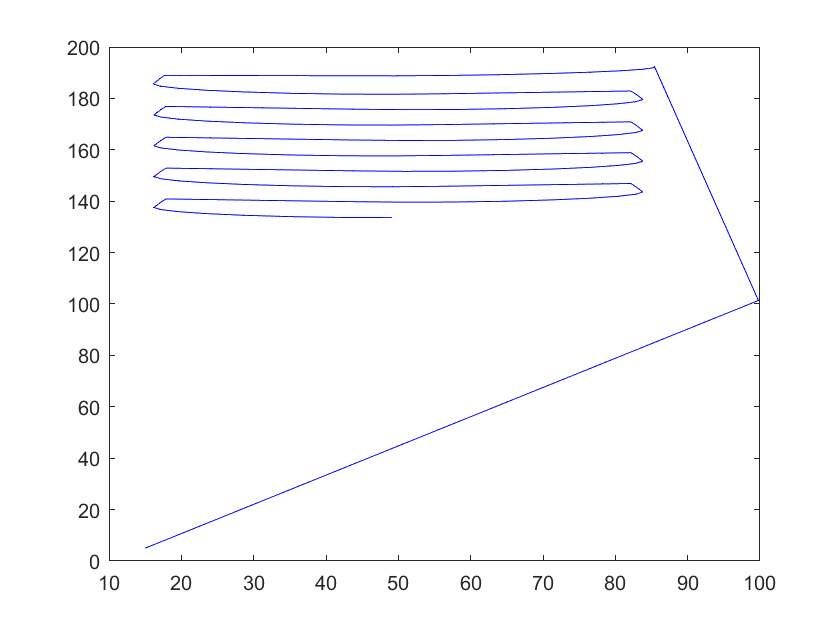

[drone, poses] = Sweep_Search_Algorithm(drone, MAX_MOVES);

sweepPathfindingPercent = getDroneStats(drone, poses)

sweepPathfindingPercent = 0.1233

function percent = getDroneStats(drone, poses)
    moves = drone.Moves;
    explored = length(drone.DroneMap(drone.DroneMap>0));
    total = size(drone.DroneMap, 1) * size(drone.DroneMap, 2);
    percent = explored / total;
end